# **電力負載分析**

**匯入資料**

data = readtable('electricity.xlsx');
head(data, 20)

       Date        Residential    Commercial    Industrial      Total   
    ___________    ___________    __________    __________    __________

    01-Jan-1990     9.542e+07     6.2499e+07    7.5188e+07    2.4087e+08
    01-Feb-1990    7.4498e+07     5.6912e+07    7.4607e+07    2.1336e+08
    01-Mar-1990    7.1902e+07      5.798e+07    7.6842e+07    2.1407e+08
    01-Apr-1990    6.5191e+07     5.6481e+07    7.6238e+07    2.0507e+08
    01-May-1990    6.2881e+07     5.8941e+07    7.8759e+07    2.0815e+08
    01-Jun-1990      7.39e+07     6.4609e+07    8.0676e+07    2.2704e+08
    01-Jul-1990    9.0935e+07     7.0948e+07    8.1116e+07    2.5159e+08
    01-Aug-1990    8.8564e+07     7.1119e+07    8.4045e+07    2.5211e+08
    01-Sep-1990     8.624e+07     6.9296e+07    8.1611e+07    2.4518e+08
    01-Oct-1990    6.9595e

**資料前處理**

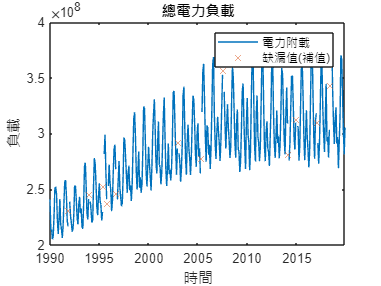

total = data.Total;
missing_idx = ismissing(total);
total_ = fillmissing(total, 'spline');

figure
plot(data.Date, total)
hold on
plot(data.Date(missing_idx), total_(missing_idx), 'x')
hold off

title("總電力負載")
xlabel('時間')
ylabel('負載')
legend(["電力附載", "缺漏值(補值)"])

**趨勢預測**

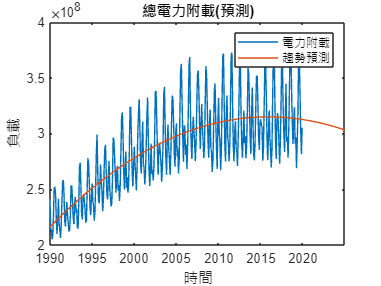

x = years(data.Date - data.Date(1));
coeff = polyfit(x, total_, 3);
x_pred = linspace(0,35,500);
x_pred_dt = data.Date(1) + years(x_pred);
y_pred = polyval(coeff, x_pred);

figure
plot(data.Date, total_)
hold on
plot(x_pred_dt, y_pred)

title("總電力附載(預測)")
xlabel('時間')
ylabel('負載')
legend(["電力附載", "趨勢預測"])